# Lab 7 – PLL Preparation Questions

This live script contains answers and supporting plots for the preparation tasks of Lab 7 – Phase-Locked Loop (PLL).

## 2.1 Output Signal of the PLL

Depending on the application, the PLL output is taken from different parts of the circuit.

clc; clear;
disp("2.1 Answers:");

2.1 Answers:


disp("a) For stabilization → output is taken after the VCO.");

a) For stabilization → output is taken after the VCO.


disp("b) For frequency synthesis → output is taken after the VCO.");

b) For frequency synthesis → output is taken after the VCO.


disp("c) For FM demodulation → output is taken after the loop filter.");

c) For FM demodulation → output is taken after the loop filter.


## 2.2 Phase Detector – XOR Circuit

The XOR phase detector provides a control voltage that varies with the phase difference between two input square waves.

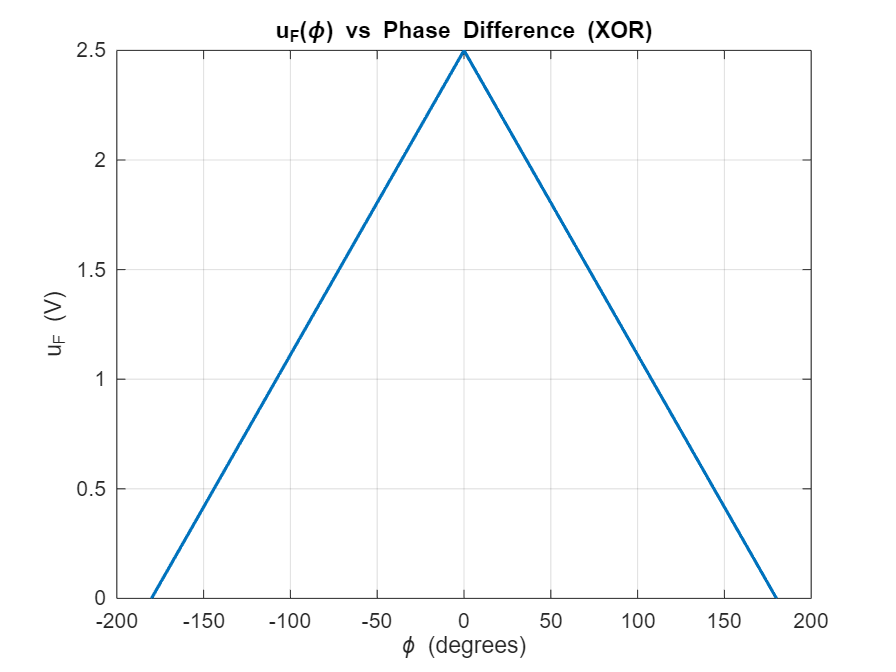

V_DD = 5;  % supply voltage
phi = -180:0.5:180;
uF_XOR = (1 - abs(phi) / 180) * (V_DD / 2);  % triangle shape

figure;
plot(phi, uF_XOR, 'LineWidth', 1.5);
title('u_F(\phi) vs Phase Difference (XOR)');
xlabel('\phi (degrees)');
ylabel('u_F (V)');
grid on;


disp("2.2.1 Answers:");

2.2.1 Answers:


disp("1. Φ = 0° → uD(t) = 0. Φ = ±90° → XOR output is 50% duty square wave.");

1. Φ = 0° → uD(t) = 0. Φ = ±90° → XOR output is 50% duty square wave.


disp("2. Frequency of uD(t) = 2× input frequency.");

2. Frequency of uD(t) = 2× input frequency.


disp("3. uF values: 0° → 0 V, ±90° → V_DD × 0.5");

3. uF values: 0° → 0 V, ±90° → V_DD × 0.5


disp("4. Triangle curve shown in plot.");

4. Triangle curve shown in plot.


## 2.2 Phase Detector – Phase-Frequency Detector (PFD)

The PFD extends the XOR by allowing detection of both phase and frequency errors over a full 2π range.

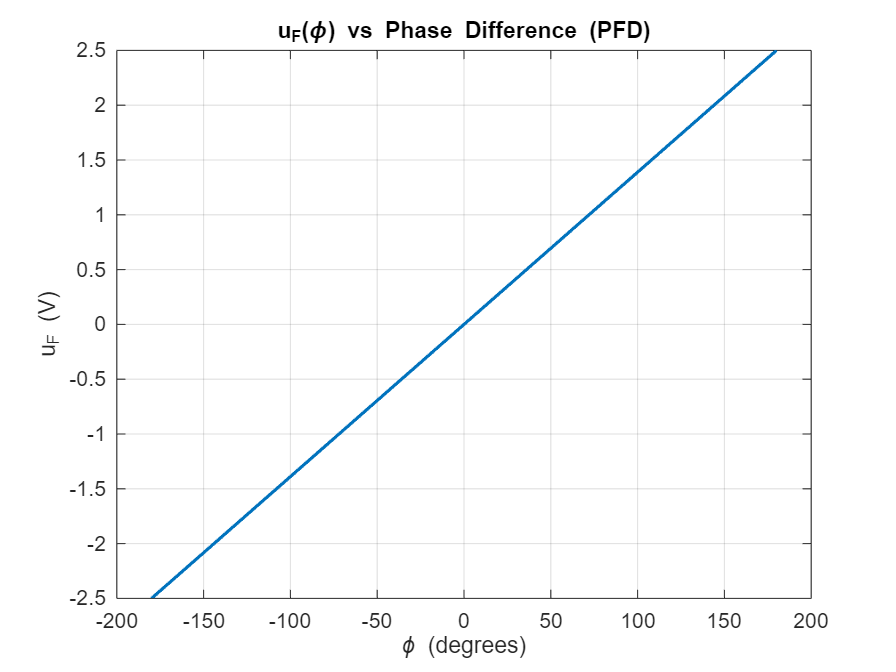

uF_PFD = (phi / 180) * (V_DD / 2);  % linear

figure;
plot(phi, uF_PFD, 'LineWidth', 1.5);
title('u_F(\phi) vs Phase Difference (PFD)');
xlabel('\phi (degrees)');
ylabel('u_F (V)');
grid on;


disp("2.2.2 Answers:");

2.2.2 Answers:


disp("1. Φ = 0° → PFD = high-Z, Φ = +90° → UP pulse, Φ = -90° → DN pulse");

1. Φ = 0° → PFD = high-Z, Φ = +90° → UP pulse, Φ = -90° → DN pulse


disp("2. Time average uF: 0 V at 0°, positive or negative depending on phase error");

2. Time average uF: 0 V at 0°, positive or negative depending on phase error


disp("3. Full ±360° control range as seen in plot.");

3. Full ±360° control range as seen in plot.


disp("4. PFD can detect both phase and frequency error → better capture range and lock-in time");

4. PFD can detect both phase and frequency error → better capture range and lock-in time


## 2.3 Circuit of the VCO in the HEF4046BT

The HEF4046BT VCO uses R1, R2, and C1 to set its frequency range.

disp("2.3 Answers:");

2.3 Answers:


disp("1. R1, R2 control charge/discharge currents; C1 sets oscillation timing.");

1. R1, R2 control charge/discharge currents; C1 sets oscillation timing.


disp("2. For 50–200 kHz with R2 = 100kΩ and VDD = 5V → choose R1 = 22kΩ, C1 = 220pF");

2. For 50–200 kHz with R2 = 100kΩ and VDD = 5V → choose R1 = 22kΩ, C1 = 220pF


## 2.4 Frequency Divider of ADF 4113

Integer-N and fractional-N calculations for different output frequencies.

f_ref = 10e6;  % 10 MHz reference
freqs = [1.7e9, 1.75e9, 1.8e9];
n_int = floor(freqs / f_ref);

disp("2.4 Answers:");

2.4 Answers:


disp("1. Divider ratios for:");

1. Divider ratios for:


disp(" - 1.7 GHz → n = " + n_int(1));

 - 1.7 GHz → n = 170


disp(" - 1.75 GHz → n = " + n_int(2));

 - 1.75 GHz → n = 175


disp(" - 1.8 GHz → n = " + n_int(3));

 - 1.8 GHz → n = 180



% 1.755 GHz with fractional division
target = 1.755e9;
n_floor = floor(target / f_ref);
rem = target - n_floor * f_ref;
tn1 = rem / f_ref;
tn = 1 - tn1;
neff = n_floor + tn1;

disp("2. 1.755 GHz achievable with fractional divider:");

2. 1.755 GHz achievable with fractional divider:


disp("   n = " + n_floor + " (" + tn*100 + "%) + n+1 = " + (n_floor+1) + " (" + tn1*100 + "%)");

   n = 175 (50%) + n+1 = 176 (50%)


disp("   Effective divider neff = " + neff);

   Effective divider neff = 175.5



% 1.752 GHz
target2 = 1.752e9;
n_floor2 = floor(target2 / f_ref);
rem2 = target2 - n_floor2 * f_ref;
tn1_2 = rem2 / f_ref;
tn2 = 1 - tn1_2;
neff2 = n_floor2 + tn1_2;

disp("3. 1.752 GHz achievable with fractional divider:");

3. 1.752 GHz achievable with fractional divider:


disp("   n = " + n_floor2 + " (" + tn2*100 + "%) + n+1 = " + (n_floor2+1) + " (" + tn1_2*100 + "%)");

   n = 175 (80%) + n+1 = 176 (20%)


disp("   Effective divider neff = " + neff2);

   Effective divider neff = 175.2


## 3.1.2.1 VCO Characteristic Curve

Simulated linear relationship from 0–5 V to 50–200 kHz VCO output

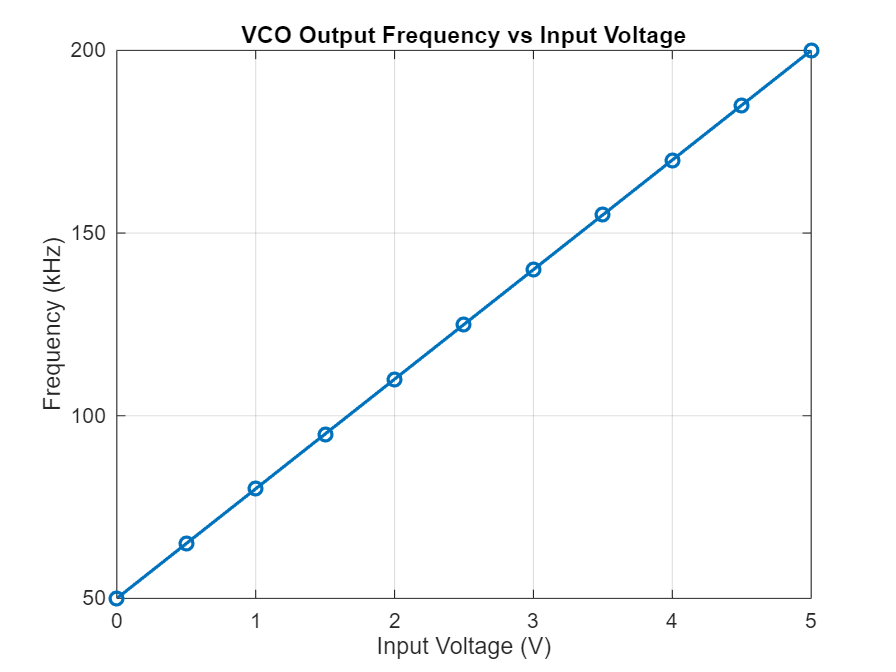

V_in = 0:0.5:5;
f_min = 50e3;
f_max = 200e3;
f_vco = f_min + ((V_in / 5) * (f_max - f_min));

figure;
plot(V_in, f_vco / 1e3, 'o-', 'LineWidth', 1.5);
title('VCO Output Frequency vs Input Voltage');
xlabel('Input Voltage (V)');
ylabel('Frequency (kHz)');
grid on;


disp("3.1.2.1 VCO curve: linear from 50 to 200 kHz across 0–5V input shown above.");

3.1.2.1 VCO curve: linear from 50 to 200 kHz across 0–5V input shown above.
